# Train Sensor Fusion Network

*Michael Caiola (Michael.Caiola@fda.hhs.gov) and Meijun Ye (Meijun.Ye@fda.hhs.gov)*

Live script used to train sensor fusion network

load("SFnet.mat","Y_Train","X_Test");    

## Visualize Sensor Fusion Double Banana layers

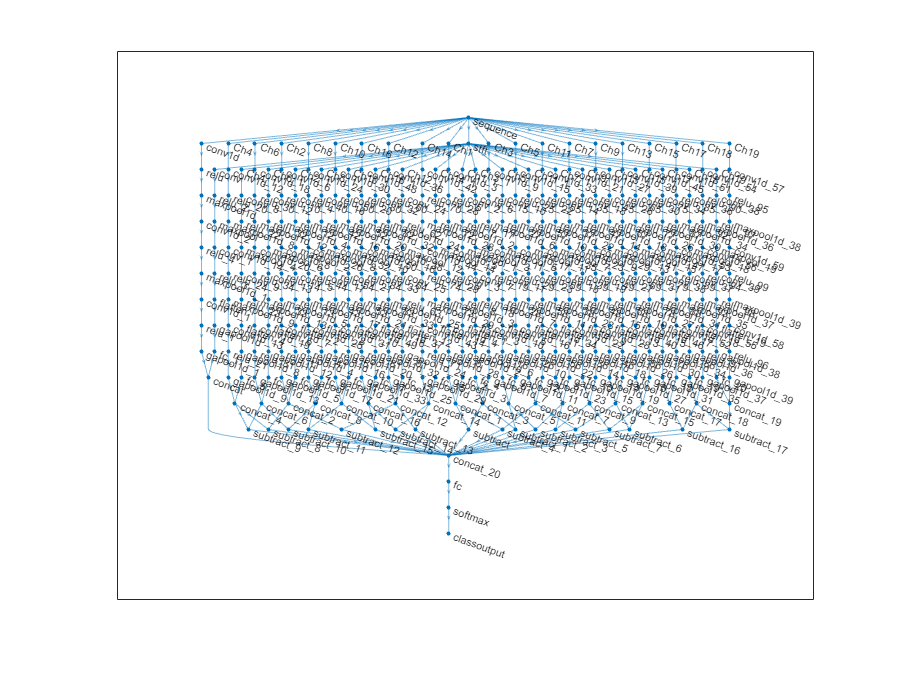

load("SFnet.mat","lgraph_2")
f = figure;
f.Position(4) = f.Position (4) *2;
f.Position(3) = f.Position (3) *2;
plot(lgraph_2)

## Train Network

Only need to do once

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:36 |       29.17% |       33.45% |      15.0494 |     145.0047 |          0.0003 |
|       1 |          50 |       00:08:18 |       37.50% |              |       4.1385 |              |          0.0003 |
|       1 |         100 |       00:16:15 |       45.83% |       45.60% |       2.2992 |       2.0721 |          0.0003 |
|       1 |         150 |       00:19:20 |       33.33% |              |       2.3187 |              |          0.0003 |
|       1 |         200 |       

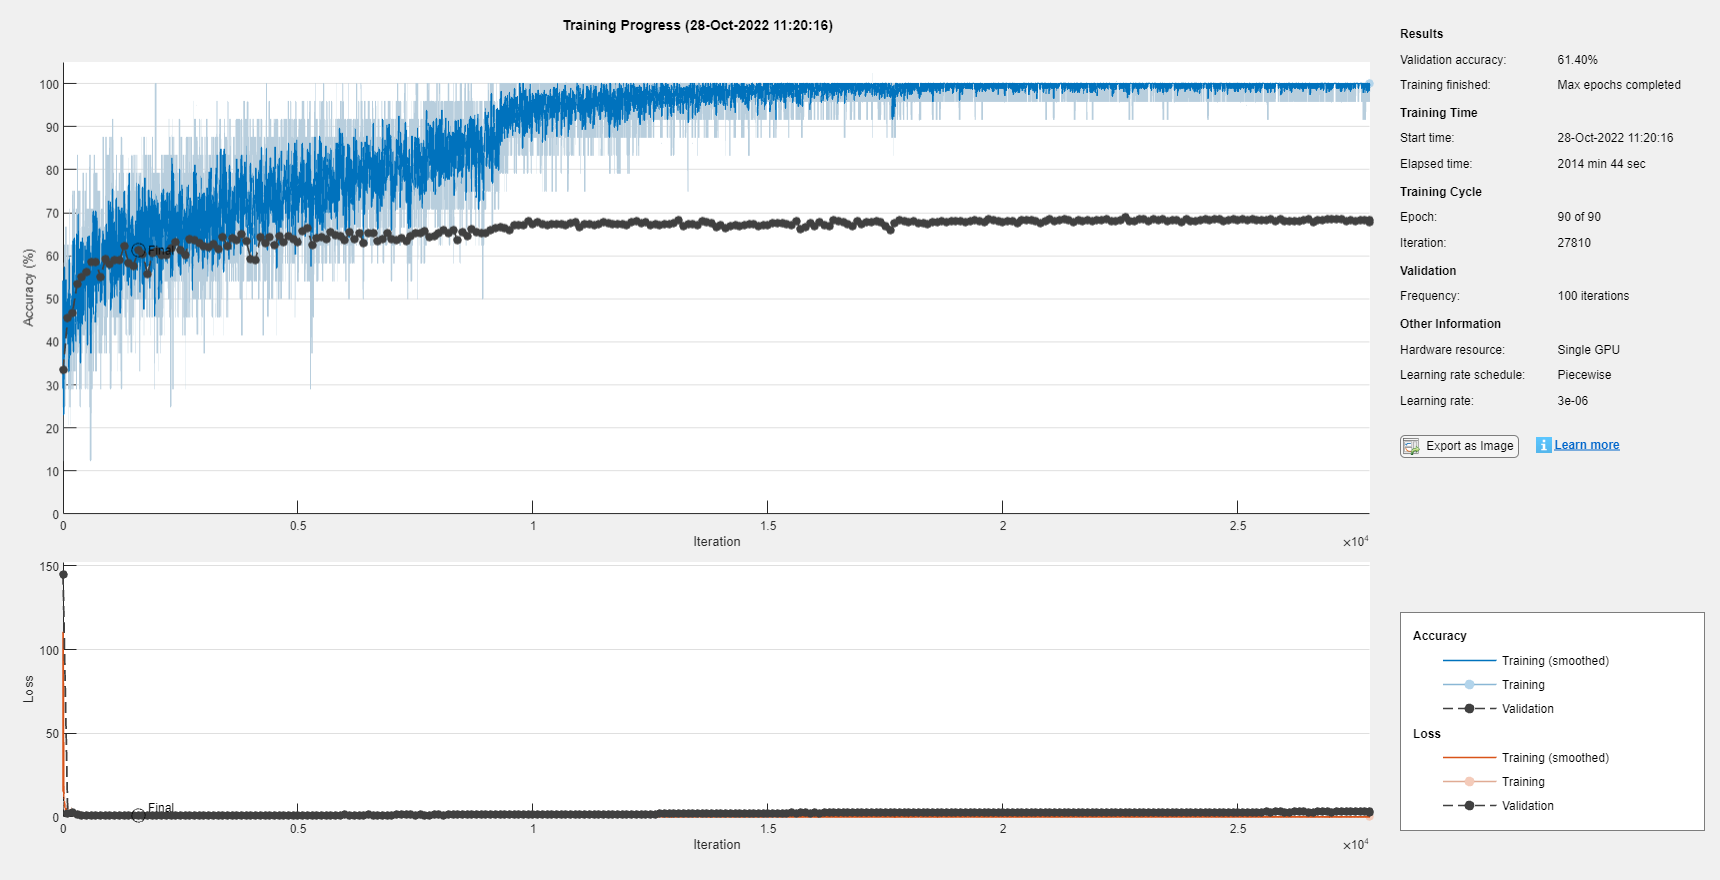

% gpuDevice(1);
% reset(Y_Train);
% reset(X_Test);
% miniBatchSize=24;
% Y_Train.MiniBatchSize=miniBatchSize;
% X_Test.MiniBatchSize=miniBatchSize;
% opts=trainingOptions("adam","Plots","training-progress","ExecutionEnvironment","gpu", ...
% "Shuffle","every-epoch","MiniBatchSize",miniBatchSize,"MaxEpochs",30*3,...
% "InitialLearnRate",3e-4,"LearnRateSchedule","piecewise","LearnRateDropPeriod",30,..."L2Regularization",.001,...
% "OutputNetwork","best-validation-loss","ValidationData",X_Test,"ValidationFrequency",100);
% bnet=trainNetwork(Y_Train,lgraph_2,opts);

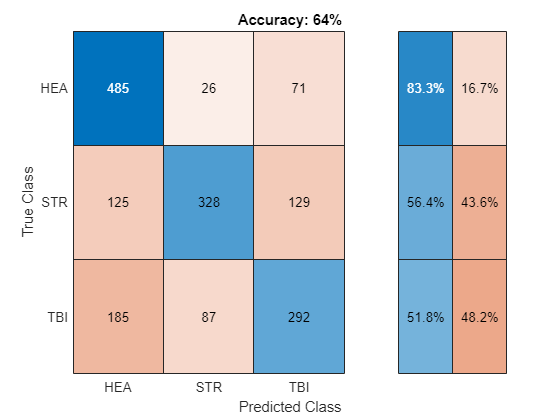

load("SFnet.mat","bnet2");
Snet = MdlResults(bnet2,X_Test,X_Test.Labels);
classify(Snet);

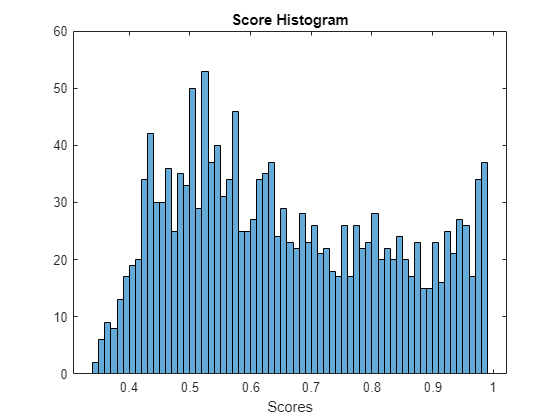

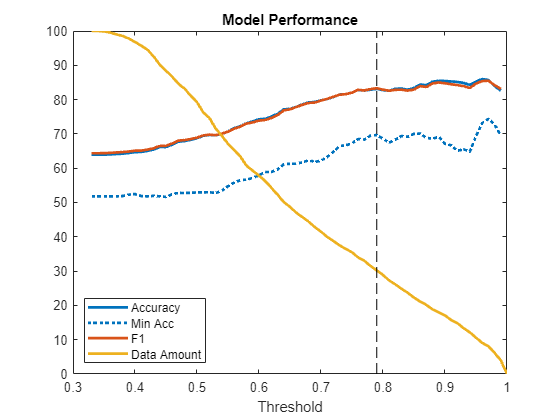

Data Remaining: 0.30208


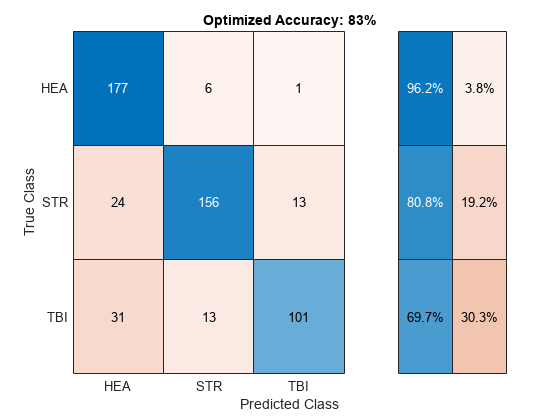

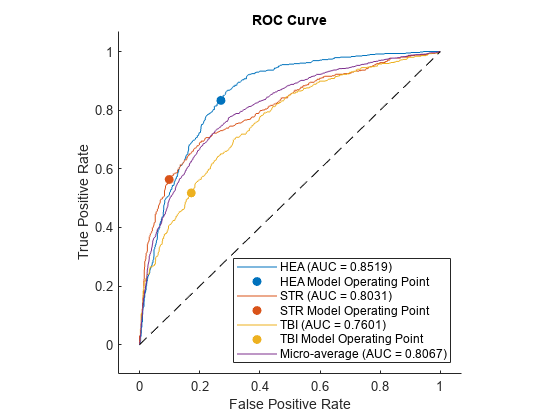

metrics(Snet);

## **Disclaimer**

This software and documentation (the "Software") were developed at the Food and Drug Administration (FDA) by employees of the Federal Government in the course of their official duties. Pursuant to Title 17, Section 105 of the United States Code, this work is not subject to copyright protection and is in the public domain. Permission is hereby granted, free of charge, to any person obtaining a copy of the Software, to deal in the Software without restriction, including without limitation the rights to use, copy, modify, merge, publish, distribute, sublicense, or sell copies of the Software or derivatives, and to permit persons to whom the Software is furnished to do so. FDA assumes no responsibility whatsoever for use by other parties of the Software, its source code, documentation or compiled executables, and makes no guarantees, expressed or implied, about its quality, reliability, or any other characteristic. Further, use of this code in no way implies endorsement by the FDA or confers any advantage in regulatory decisions. Although this software can be redistributed and/or modified freely, we ask that any derivative works bear some notice that they are derived from it, and any modified versions bear some notice that they have been modified.